# Create and Customize Scatter Histograms from Tablular Data

`scatterhistogram` creates a scatter plot with marginal histograms from a table. The table data includes a two variables, one to display along the *x*-axis and another across the *y*-axis.

### Load Table Data

Load the `patients` data set and create a table from a subset of the variables loaded into the workspace.

load patients
tbl = table(LastName,Diastolic,Systolic,Smoker);

### Basic Scatterhistogram Plot

Create a scatter histogram chart comparing the H`eight` values to the W`eight` values.

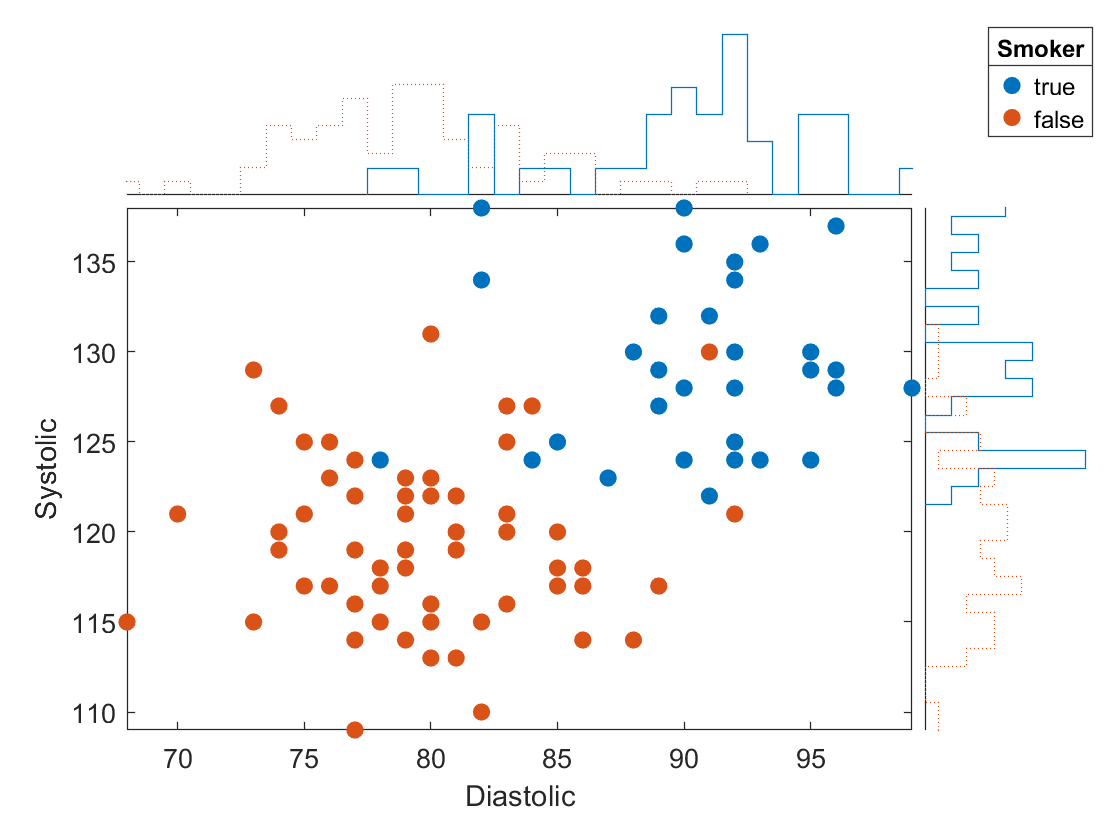

scatterhistogram(tbl,'Diastolic','Systolic','GroupVariable','Smoker');

## Customizations

### Specify Histogram Chart Appearance

Create a scatter plot with marginal histograms. Specify the number of bins and line widths of the histograms, the location of the scatter plot, and the legend visibility. Adjust the histograms by specifying the *NumBins* and *LineWidth* properties. Place the scatter plot in the `'NorthEast'` location of the figure by using the *ScatterPlotLocation* property. Ensure the legend is visible by specifying the *LegendVisible* property as `'on'`.

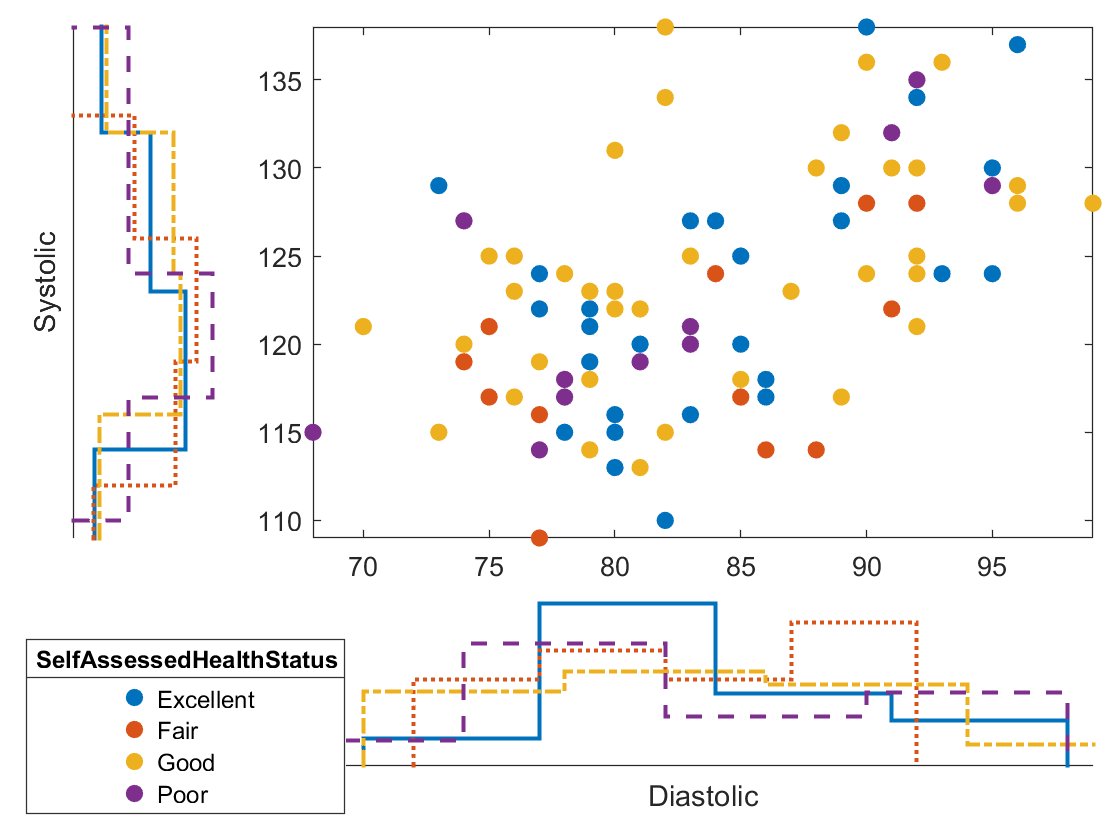

tbl = table(LastName,Diastolic,Systolic,SelfAssessedHealthStatus);
scatterhistogram(tbl,'Diastolic','Systolic', ...
    'GroupVariable','SelfAssessedHealthStatus', ...
    'NumBins',4,...                                                      % Specify histogram bins
    'LineWidth',1.5,...                                                  % Set lin thickness
    'ScatterPlotLocation','NorthEast',...                                % Specify plot layout
    'LegendVisible','on');                                               % Add a legend

### Visualize Data Using a Density Plot

Load the `carsmall` data set and create a scatter histogram chart from the data. Compare the `Horsepower` and `MPG` values. Use the number of cylinders to group the data by setting the `GroupVariable` option to `Cylinders`. Specify density histograms by setting the *HistogramDisplayStyle* property to `'smooth'.`

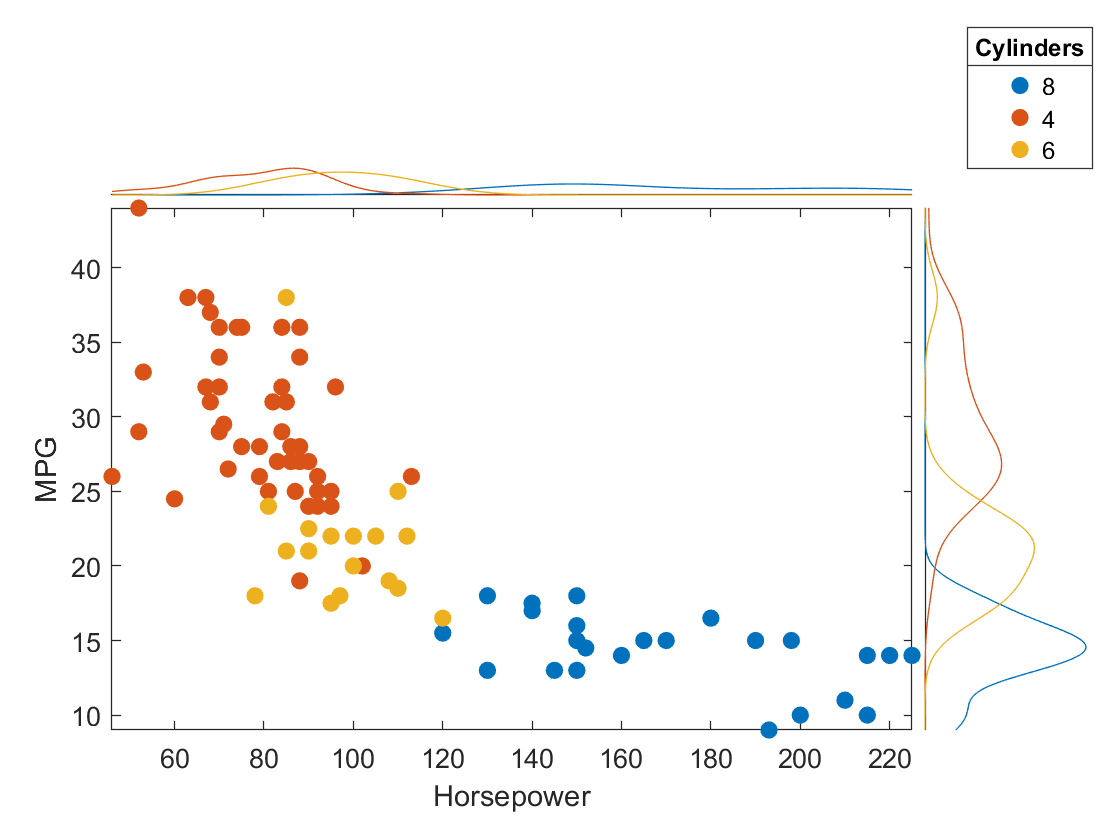

load carsmall
tbl = table(Horsepower,MPG,Cylinders);
sh = scatterhistogram(tbl,'Horsepower','MPG', ...
    'GroupVariable','Cylinders',...
    'HistogramDisplayStyle','smooth', ...                       % Specify histogram to be density funciton
    'LineStyle','-');                                           % Specify a consistent line style for all the data                

## Additional Information

### Get All Scatterhistogram Properties

Graphics objects in MATLAB have many properties. To see all the properties of a scatterhistogram, uncomment the following code

% get(sh)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[scatterhistogram](https://www.mathworks.com/help/matlab/ref/scatterhistogram.html)